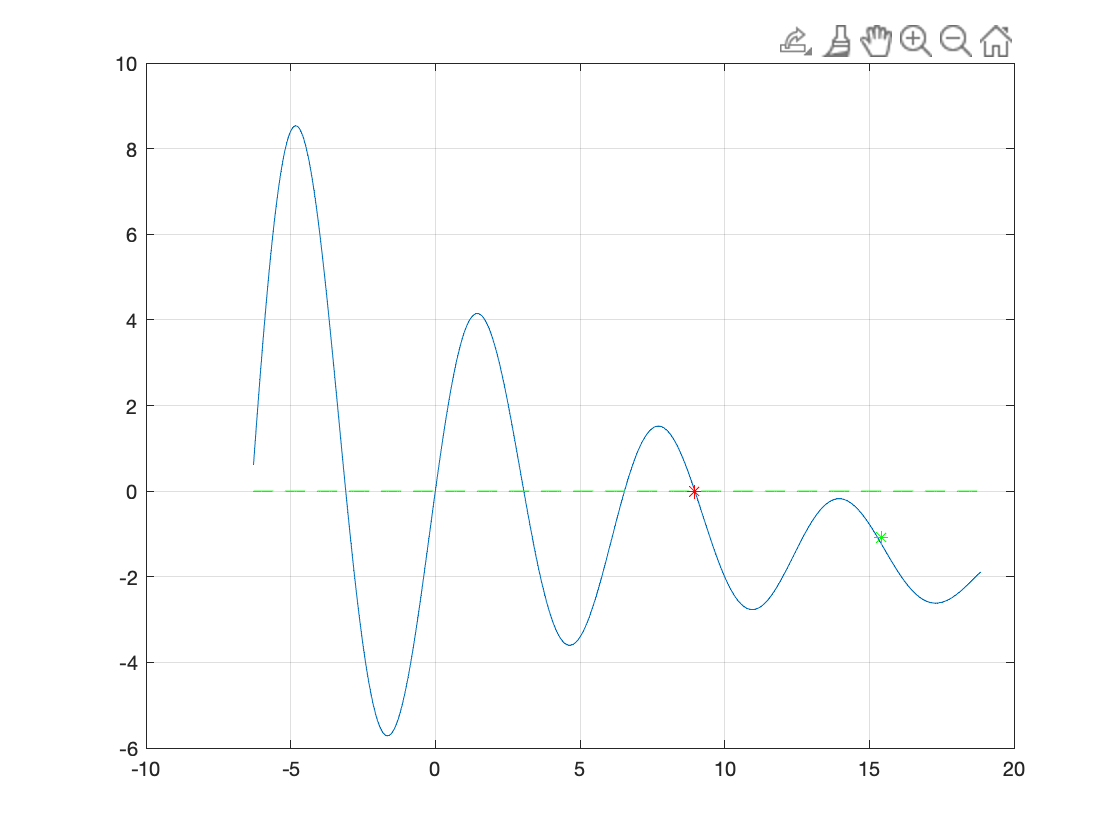

x = -2*pi:0.01:6*pi;
fx = 5*(exp(-0.1*x)).*sin(x)-0.1*x;
figure
plot(x,fx)
grid on
hold on
plot(x,0*x, "LineStyle","- -", "Color", 'green');

z = ginput(1);
plot(z(1), z(2), "*", "Color",'green');
y = @(x) 5*(exp(-0.1*x)).*sin(x)-0.1*x;
[zr,fr] = fzero(y,z(1));
hold on

plot(zr,fr, "*", "Color",'red');